clear; clc;

% test_csv = readmatrix("motor_data/ramp_0_100_1_with_load.csv");
% test_csv = readmatrix("motor_data/sin_664_v2.csv");
test_csv = readmatrix("motor_data/sin_664_with_load.csv");

test_csv(2,2)

ans = 9929203

data_length = length(test_csv(:,2))-1

data_length = 5628

time = test_csv(2:data_length+1, 2);    % мкс
ticks = test_csv(2:data_length+1, 3) / 15000 * 2 * pi;  % рад
% ticks = test_csv(2:data_length+1, 3);  % рад
input = test_csv(2:data_length+1, 4) / 100 * 12;    % В
current = test_csv(2:data_length+1, 5) / 1000;  % А
current_orig = current;

t_start = time(1);
time = (time - t_start)/1000000;    % с

dticks = zeros(1, data_length);
dticks_orig = zeros(1, data_length);
dticks_smooth = zeros(1, data_length);

ddticks = zeros(1, data_length);
ddticks_orig = zeros(1, data_length);

dI = zeros(1, data_length);
dI_orig = zeros(1, data_length);

f_w = 1

f_w = 1

f_b = 0.7

f_b = 0.7000

f_i = 1

f_i = 1

f_di = 0.05

f_di = 0.0500

dt = time(2)-time(1)

dt = 0.0027


% ticks = smooth(ticks, 3);

for k = 2:data_length
    dt = time(k)-time(k-1);

    dticks_orig(k) = ( ticks(k)-ticks(k-1) )/dt;
    ddticks_orig(k) = ( dticks_orig(k)-dticks_orig(k-1) )/dt;
    dI_orig(k) = ( current(k)-current(k-1) )/dt;

%     dticks(n) = ( ticks(n)-ticks(n-1) )/dt;
    dticks(k) = dticks(k-1)*(1-f_w) + f_w * ( ticks(k)-ticks(k-1) )/dt;

%     ddticks(n) = ( dticks(n)-dticks(n-1) )/dt;
%     ddticks(n) = ddticks(n-1)*(1-f_b) + f_b * ( dticks(n)-dticks(n-1) )/dt;
    ddticks(k) = ddticks(k-1)*(1-f_b) + f_b * ( dticks_orig(k)-dticks_orig(k-1) )/dt;
    
%     current(n) = current(n-1)*(1-f_i) + f_i * current(n);

%     dI(n) = ( current(n)-current(n-1) )/dt;
    dI(k) = dI(k-1)*(1-f_di) + f_di * ( current(k)-current(k-1) )/dt;
end

dticks = smooth(dticks, 3);

% works for sin_664.csv
current = smooth(current, 3);
ddticks = smooth(ddticks, 12);
dI = smooth(dI, 5);

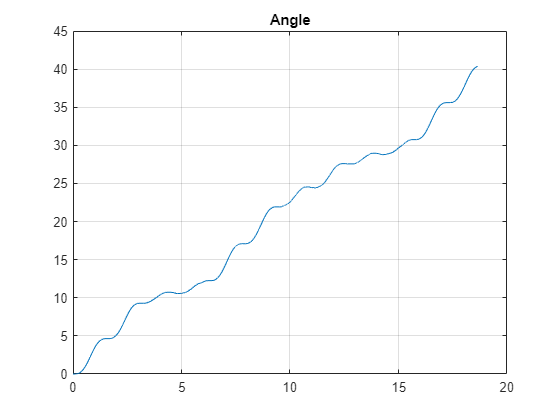

figure;
plot(time, ticks)
title("Angle")
xlim("auto")
ylim("auto")
grid on

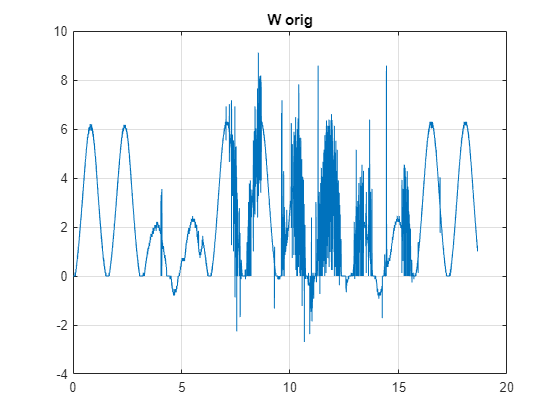


plot(time, dticks_orig)
title("W orig")
xlim("auto")
ylim("auto")
grid on

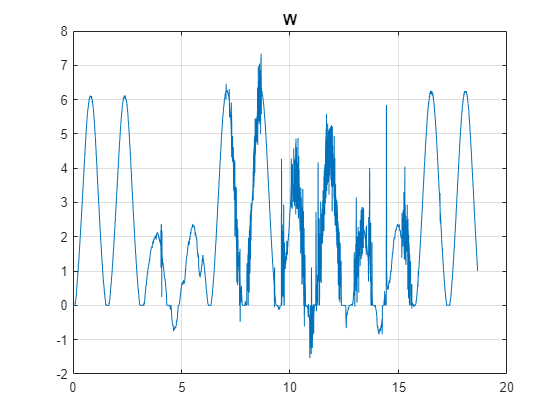


plot(time, dticks)
% hold
% plot(time, dticks_orig)
% hold 
title("W")
xlim("auto")
ylim("auto")
grid on

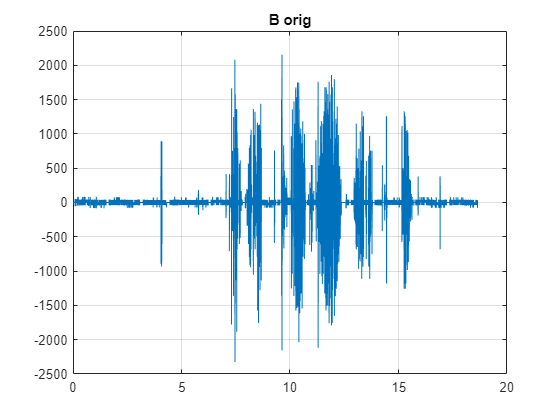


% plot(time_smooth, dticks_smooth)
% % plot(time, dticks_smooth)
% title("W smooth")
% xlim("auto")
% ylim("auto")
% grid on

plot(time, ddticks_orig)
title("B orig")
xlim("auto")
ylim("auto")
grid on

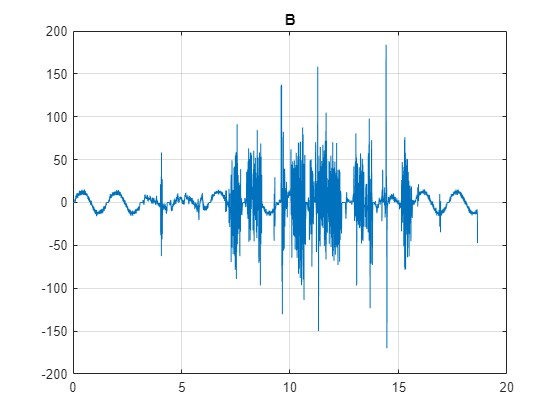


plot(time, ddticks)
title("B")
xlim("auto")
ylim("auto")
grid on

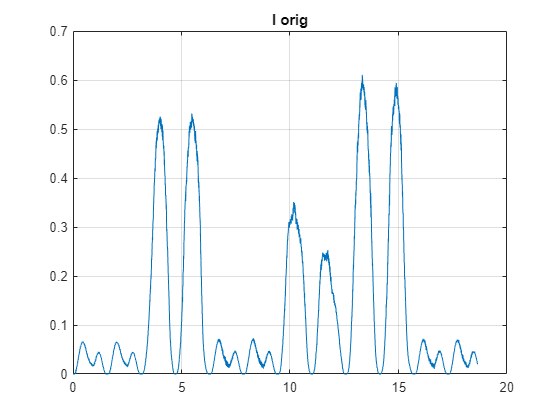


plot(time, current_orig)
title("I orig")
xlim("auto")
ylim("auto")
grid on

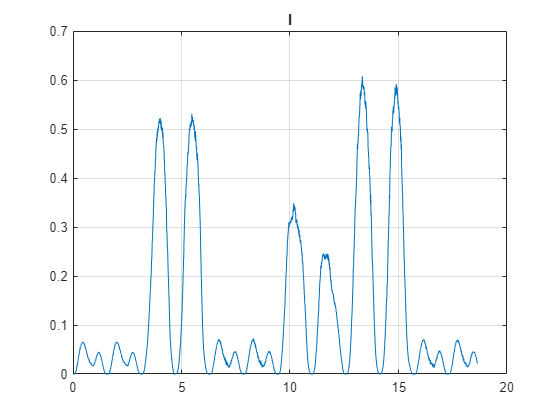


plot(time, current)
title("I")
xlim("auto")
ylim("auto")
grid on

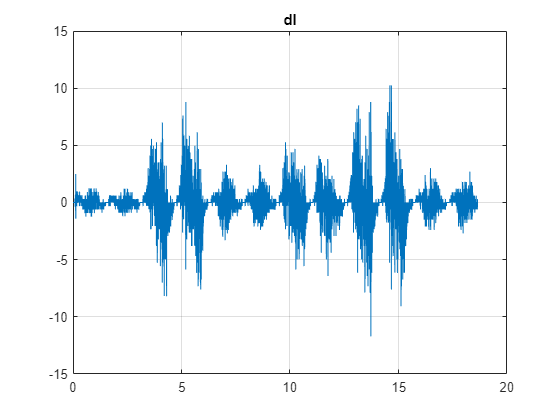


plot(time, dI_orig)
title("dI orig")
xlim("auto")
ylim("auto")
grid on

title("dI")

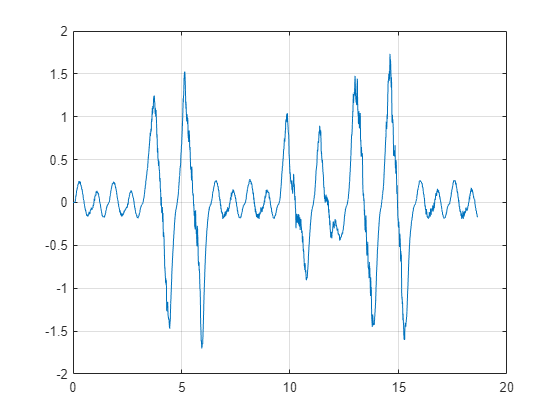

plot(time, dI)
xlim("auto")
ylim("auto")
grid on

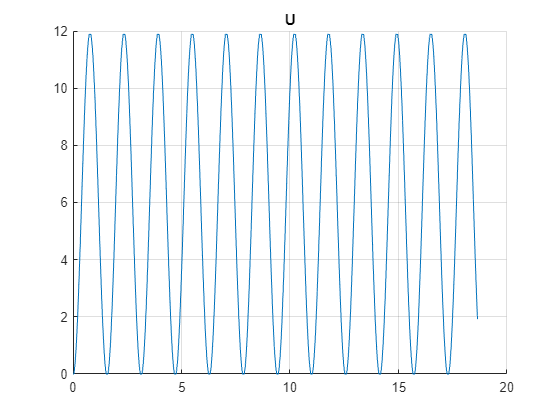


figure
title("U")
hold on
plot(time, input)
% plot(time, dticks)
hold off
xlim("auto")
ylim("auto")
grid on

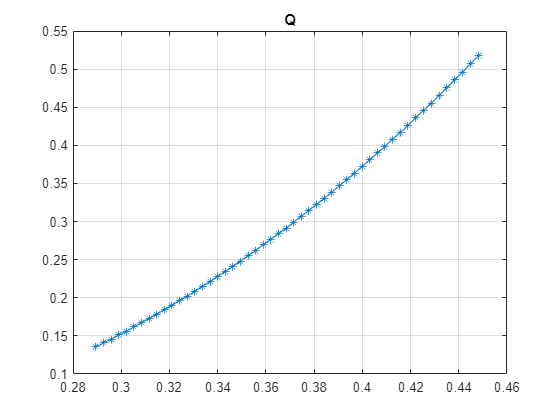


start = 100;
finish = 150;

figure;
plot(time(start:finish), ticks(start:finish), '*-')
title("Q")
xlim("auto")
ylim("auto")
grid on

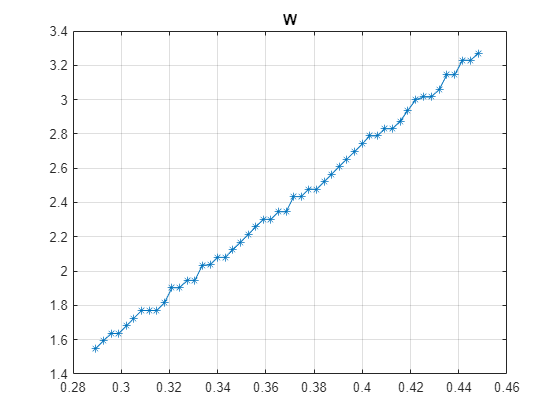


figure;
plot(time(start:finish), dticks(start:finish), '*-')
title("W")
xlim("auto")
ylim("auto")
grid on

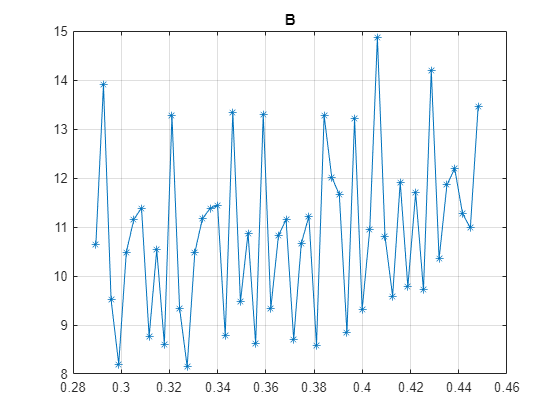


figure;
plot(time(start:finish), ddticks(start:finish), '*-')
title("B")
xlim("auto")
ylim("auto")
grid on

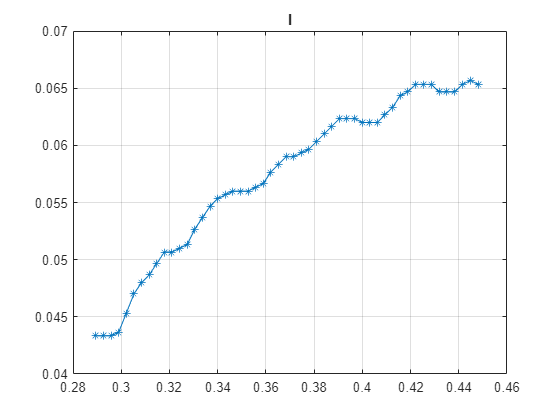


figure;
plot(time(start:finish), current(start:finish), '*-')
title("I")
xlim("auto")
ylim("auto")
grid on

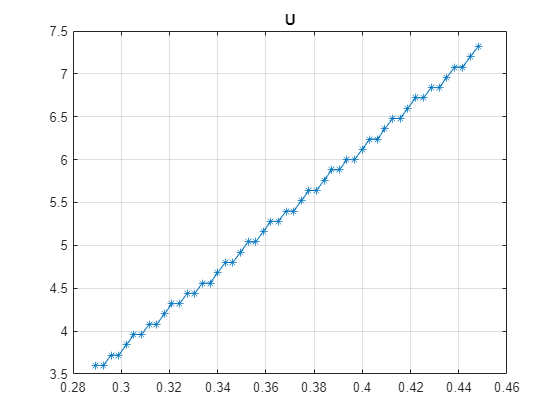


figure;
plot(time(start:finish), input(start:finish), '*-')
title("U")
xlim("auto")
ylim("auto")
grid on

### Kalman filter state estimation parameters with load

% from offline parameter identification with KF
L = 1.0551;
R = 5.9043;
Kw = 1.9437;
Km = 1.9437;
J = 0.0085;
Lam = 0.0020;

%from offline parameter identification with KF and model (with load)
% L = 0.9343;
% R = 5.9055;
% Kw = 1.9448;
% Km = 1.9448;
% J = 0.0085;
% Lam = 0.0020;  

% V3 + load
% x = [w dw I]'
% u = [Mext u]'
A = [-Lam/J      0      Km/J;
     -Km*Kw/(J*L) -Lam/J -Km*R/(J*L);
     -Kw/L       0      -R/L]

A = 1.0e+03 *

   -0.0002         0    0.2287
   -0.4213   -0.0002   -1.2796
   -0.0018         0   -0.0056


B = [1/J 0;
     0   Km/(J*L);
     0   1/L]

B =   117.6471         0
         0  216.7288
         0    0.9478


C = eye(3)

C =      1     0     0
     0     1     0
     0     0     1


C_lqe = [1 0 0;
         0 1 0;
         0 0 0]

C_lqe =      1     0     0
     0     1     0
     0     0     0


D = [0 0 0]'

D =      0
     0
     0



[Te, De] = eig(A)

Te =    0.0000 + 0.0000i  -0.0069 - 0.0481i  -0.0069 + 0.0481i
   1.0000 + 0.0000i   0.9988 + 0.0000i   0.9988 + 0.0000i
   0.0000 + 0.0000i   0.0044 - 0.0000i   0.0044 + 0.0000i


De =   -0.2353 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -2.9156 +20.3488i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -2.9156 -20.3488i


Cc = ctrb(A,B)

Cc = 1.0e+05 *

    0.0012         0   -0.0003    0.0022   -0.4955   -0.0126
         0    0.0022   -0.4956   -0.0126    3.0066   -0.8421
         0    0.0000   -0.0022   -0.0001    0.0126   -0.0037


Cob = obsv(A, C_lqe)

Cob = 1.0e+04 *

    0.0001         0         0
         0    0.0001         0
         0         0         0
   -0.0000         0    0.0229
   -0.0421   -0.0000   -0.1280
         0         0         0
   -0.0421         0   -0.1333
    0.2556    0.0000   -8.8867
         0         0         0


rank(Cc)

ans = 3

rank(Cob)

ans = 3


Vd_w = 4e1;
Vd_dw = 1e1;
Vd_I = 1;
Vd = [Vd_w   0    0;
       0   Vd_dw  0;
       0     0    Vd_I];

Vn = [2 0 0;
      0 3e3 0;
      0 0 1];

% Vd_w = 1;
% Vd_dw = 1;
% Vd_I = 1;
% Vd = [Vd_w   0    0;
%        0   Vd_dw  0;
%        0     0    Vd_I];
% 
% Vn = [1e6 0 0;
%       0 1e6 0;
%       0 0 1];

dt = 0.005

dt = 0.0050

% [Kf, Pf, Ef] = lqed(A, Vd, C_lqe, Vd, Vn, 0.009); %115200 uart
% [Kf, Pf, Ef] = lqed(A, Vd, C_lqe, Vd, Vn, 0.0015); % 250000 uart
[Kf, Pf, Ef] = lqed(A, Vd, C_lqe, Vd, Vn, dt);
Kf

Kf =     0.5741   -0.0008         0
   -1.2459    0.0401         0
   -0.0049    0.0001         0


" << " + Kf(1,1) + ", " + Kf(1,2) + ", " + Kf(1,3) + ", " ...
       + Kf(2,1) + ", " + Kf(2,2) + ", " + Kf(2,3) + ", " ...
       + Kf(3,1) + ", " + Kf(3,2) + ", " + Kf(3,3) + ";"

ans = " << 0.57409, -0.00083062, 0, -1.2459, 0.040101, 0, -0.0049334, 9.3286e-05, 0;"


[Te, De] = eig(A);
Cc = ctrb(A,B)

Cc = 1.0e+05 *

    0.0012         0   -0.0003    0.0022   -0.4955   -0.0126
         0    0.0022   -0.4956   -0.0126    3.0066   -0.8421
         0    0.0000   -0.0022   -0.0001    0.0126   -0.0037


Cob = obsv(A, C_lqe)

Cob = 1.0e+04 *

    0.0001         0         0
         0    0.0001         0
         0         0         0
   -0.0000         0    0.0229
   -0.0421   -0.0000   -0.1280
         0         0         0
   -0.0421         0   -0.1333
    0.2556    0.0000   -8.8867
         0         0         0


rank(Cc)

ans = 3

rank(Cob)

ans = 3

### KF estimation on raw data

x = [0 0 0]';
u = [0 0]';
x_arr = zeros(3, data_length);
q_arr = zeros(1, data_length);
Mext = 0;
Mext_arr = zeros(1, data_length);

[Te, De] = eig(A)

Te =    0.0000 + 0.0000i  -0.0069 - 0.0481i  -0.0069 + 0.0481i
   1.0000 + 0.0000i   0.9988 + 0.0000i   0.9988 + 0.0000i
   0.0000 + 0.0000i   0.0044 - 0.0000i   0.0044 + 0.0000i


De =   -0.2353 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -2.9156 +20.3488i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -2.9156 -20.3488i


At = expm(A*dt)

At =     0.9936   -0.0000    1.1249
   -2.0710    0.9988   -7.4857
   -0.0091   -0.0000    0.9672


Bt = Te*inv(De)*inv(Te)*(Te*expm(De*dt)*inv(Te)-eye(3))*B;
Bt = real(Bt)

Bt =     0.5869    0.0027
   -0.6127    1.0661
   -0.0027    0.0047


A_hat = (At-Kf*C_lqe)

A_hat =     0.4195    0.0008    1.1249
   -0.8251    0.9587   -7.4857
   -0.0041   -0.0001    0.9672


B_hat = [Bt Kf]

B_hat =     0.5869    0.0027    0.5741   -0.0008         0
   -0.6127    1.0661   -1.2459    0.0401         0
   -0.0027    0.0047   -0.0049    0.0001         0


" << " + At(1,1) + ", " + At(1,2) + ", " + At(1,3) + ", " ...
       + At(2,1) + ", " + At(2,2) + ", " + At(2,3) + ", " ...
       + At(3,1) + ", " + At(3,2) + ", " + At(3,3) + ";"

ans = " << 0.99362, -7.8978e-20, 1.1249, -2.071, 0.99882, -7.4857, -0.009062, -7.4284e-23, 0.96725;"

" << " + Bt(1,1) + ", " + Bt(1,2) + ", "...
       + Bt(2,1) + ", " + Bt(2,2) + ", "...
       + Bt(3,1) + ", " + Bt(3,2) + ";"

ans = " << 0.58687, 0.0026806, -0.61274, 1.0661, -0.0026806, 0.004665;"

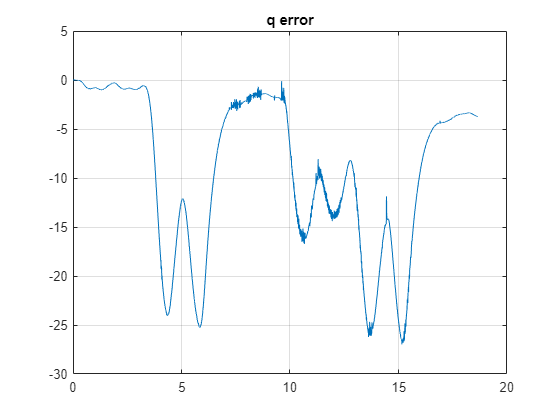


for k = 1:data_length-1
    u_act = input(k);
    u = [real(Mext) u_act (C_lqe*[dticks(k) ddticks(k) current(k)]')']';
    x_arr(:, k+1) = A_hat*x_arr(:, k)+B_hat*u;

    Mext = J*x_arr(2, k) + Lam*x_arr(1,k) - Km*x_arr(3,k);

    dt = time(k+1)-time(k);
    q_arr(k+1) = q_arr(k) + x_arr(1, k)*dt;
    Mext_arr(k) = real(Mext);
end

x_arr = real(x_arr);

% x_arr_d2 = x_arr;
% t_d2 = t;
% t = linspace(ts, tf, num_of_steps);
% q_err = ticks - q_m';

figure
plot(time, (ticks'-real(q_arr))*180/pi)
% plot(time, q_arr)
grid on
title("q error degrees")
xlim("auto")
ylim("auto")

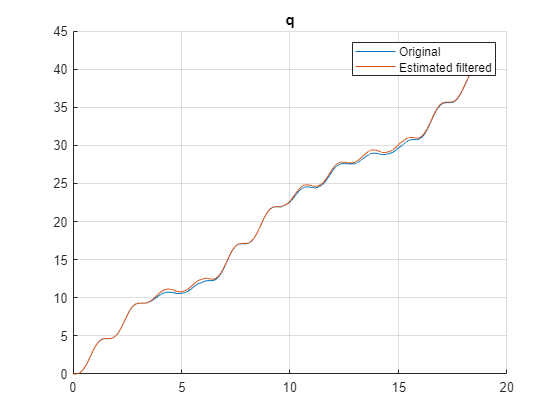


% figure
% plot(time, dticks'-real(x_arr(1, :)))
% % plot(time, q_arr)
% grid on
% title("dq error")
% xlim("auto")
% ylim("auto")

figure
hold on
plot(time, ticks)
plot(time, real(q_arr))
hold off
grid on
title("q")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

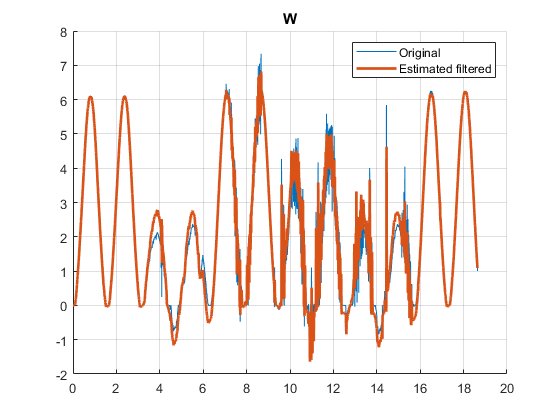


figure
hold on
% plot(time, dticks_orig)
plot(time, dticks)
plot(time, x_arr(1, :), "LineWidth", 2)
hold off
grid on
title("W")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

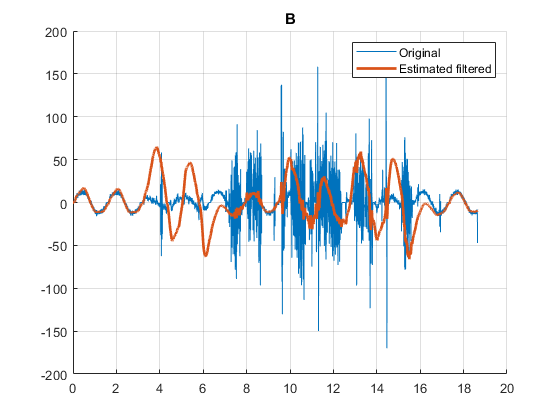


figure
hold on
% plot(time, ddticks_orig)
plot(time, ddticks)
plot(time, x_arr(2, :), "LineWidth", 2)
% plot(time, x_arr(2, :), "LineWidth", 2, "LineStyle", '--')
hold off
grid on
title("B")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

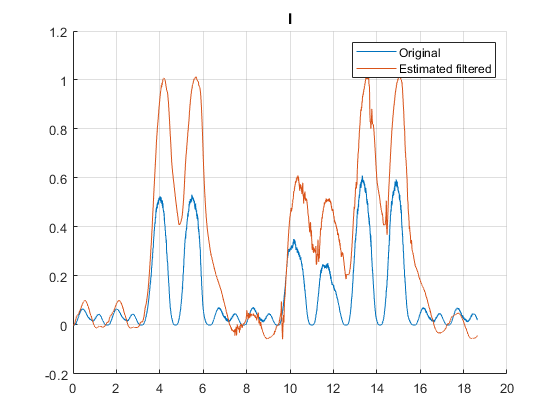


figure
hold on
plot(time, current_orig)
plot(time, x_arr(3, :))
hold off
grid on
title("I")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

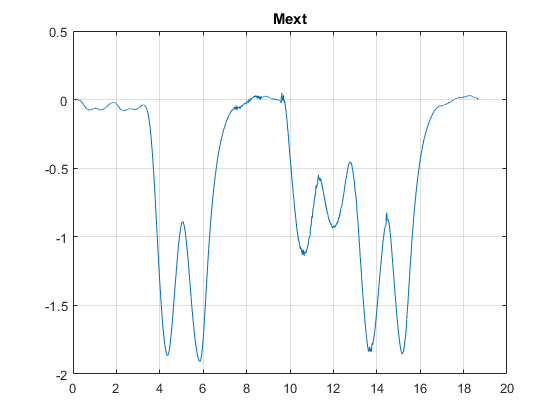


figure
plot(time, Mext_arr)
grid on
title("Mext")
xlim("auto")
ylim("auto")

### Kalman filter state estimation parameters

% from offline parameter identification with KF
L = 1.0551;
R = 5.9043;
Kw = 1.9437;
Km = 1.9437;
J = 0.0085;
Lam = 0.0020;

% V3
% x = [w dw I]'
% u = u
A = [-Lam/J      0      Km/J;
     -Km*Kw/(J*L) -Lam/J -Km*R/(J*L);
     -Kw/L       0      -R/L]

A = 1.0e+03 *

   -0.0002         0    0.2287
   -0.4213   -0.0002   -1.2796
   -0.0018         0   -0.0056


inv(A)

ans =    -0.0132    0.0000   -0.5411
    0.0000   -4.2500  971.8500
    0.0044    0.0000   -0.0006


B = [0 Km/(J*L) 1/L]'

B =          0
  216.7288
    0.9478


C = eye(3)

C =      1     0     0
     0     1     0
     0     0     1


D = [0 0 0]'

D =      0
     0
     0



% no load
Vd_w = 4e1;
Vd_dw = 1e1;
Vd_I = 1;
Vd = [Vd_w   0    0;
       0   Vd_dw  0;
       0     0    Vd_I];
Vn = [2 0 0;
      0 1e3 0;
      0 0 1];

% with load
% Vd_w = 1e3;
% Vd_dw = 1e3;
% Vd_I = 1e-6;
% Vd = [Vd_w   0    0;
%        0   Vd_dw  0;
%        0     0    Vd_I];
% Vn = [1 0 0;
%       0 1 0;
%       0 0 1e6];

C_lqe = [1 0 0;
         0 1 0;
         0 0 0];

% [Kf, Pf, Ef] = lqed(A, Vd, C_lqe, Vd, Vn, 0.009);
[Kf, Pf, Ef] = lqed(A, Vd, C_lqe, Vd, Vn, 0.0015);
Kf

Kf =     0.2313   -0.0009         0
   -0.4641    0.0229         0
   -0.0018    0.0001         0



[Te, De] = eig(A);
Cc = ctrb(A,B)

Cc = 1.0e+04 *

         0    0.0217   -0.1264
    0.0217   -0.1264   -8.4214
    0.0001   -0.0005   -0.0370


Cob = obsv(A, C_lqe)

Cob = 1.0e+04 *

    0.0001         0         0
         0    0.0001         0
         0         0         0
   -0.0000         0    0.0229
   -0.0421   -0.0000   -0.1280
         0         0         0
   -0.0421         0   -0.1333
    0.2556    0.0000   -8.8867
         0         0         0


rank(Cc)

ans = 2

rank(Cob)

ans = 3

### KF estimation on raw data

x = [0 0 0]';
u = [0 0]';
x_arr = zeros(3, data_length);
q_arr = zeros(1, data_length);

[Te, De] = eig(A)

Te =    0.0000 + 0.0000i  -0.0069 - 0.0481i  -0.0069 + 0.0481i
   1.0000 + 0.0000i   0.9988 + 0.0000i   0.9988 + 0.0000i
   0.0000 + 0.0000i   0.0044 - 0.0000i   0.0044 + 0.0000i


De =   -0.2353 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -2.9156 +20.3488i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -2.9156 -20.3488i


At = expm(A*dt)

At =     0.9990         0    0.3759
   -0.6923    0.9996   -2.2344
   -0.0030         0    0.9902


Bt = Te*inv(De)*inv(Te)*(Te*expm(De*dt)*inv(Te)-eye(3))*B

Bt =    0.0003 - 0.0000i
   0.3562 + 0.0000i
   0.0016 - 0.0000i


A_hat = (At-Kf*C_lqe)

A_hat =     0.7677    0.0009    0.3759
   -0.2282    0.9767   -2.2344
   -0.0012   -0.0001    0.9902


B_hat = [Bt Kf]

B_hat =    0.0003 - 0.0000i   0.2313 + 0.0000i  -0.0009 + 0.0000i   0.0000 + 0.0000i
   0.3562 + 0.0000i  -0.4641 + 0.0000i   0.0229 + 0.0000i   0.0000 + 0.0000i
   0.0016 - 0.0000i  -0.0018 + 0.0000i   0.0001 + 0.0000i   0.0000 + 0.0000i


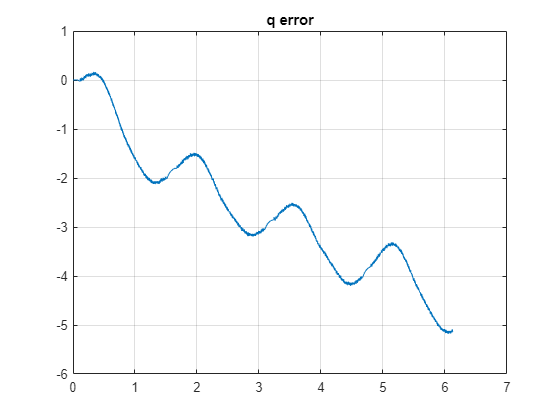


for k = 1:data_length-1
    u_act = input(k);
    u = [u_act (C_lqe*[dticks(k) ddticks(k) current(k)]')']';
    x_arr(:, k+1) = A_hat*x_arr(:, k)+B_hat*u;
    x_arr(:, k+1) = real(x_arr(:, k+1));
    dt = time(k+1)-time(k);
    q_arr(k+1) = q_arr(k) + x_arr(1, k)*dt;
end

start = 1;
% finish = 500;
finish = data_length;

figure
plot(time, (ticks'-real(q_arr))*180/pi)
% plot(time, q_arr)
grid on
title("q error")
xlim("auto")
ylim("auto")

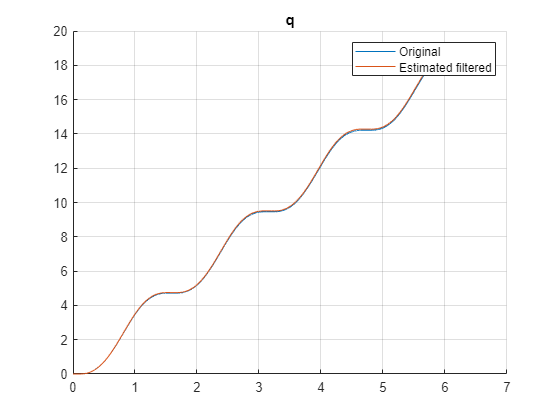


% figure
% plot(time, dticks'-real(x_arr(1, :)))
% % plot(time, q_arr)
% grid on
% title("dq error")
% xlim("auto")
% ylim("auto")

figure
hold on
plot(time(start:finish), ticks(start:finish))
plot(time(start:finish), q_arr(start:finish))
hold off
grid on
title("q")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

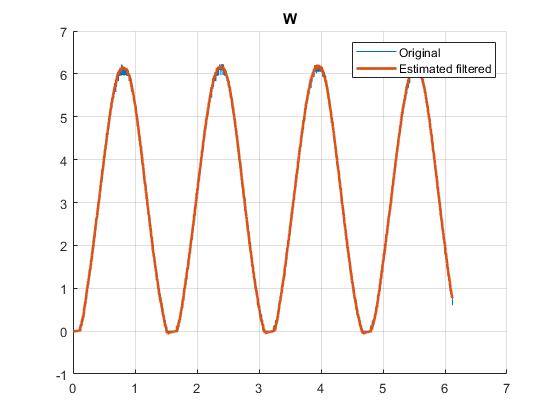


figure
hold on
% plot(time(start:finish), dticks_orig(start:finish))
plot(time(start:finish), dticks(start:finish))
plot(time(start:finish), x_arr(1, start:finish), "LineWidth", 2)
hold off
grid on
title("W")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

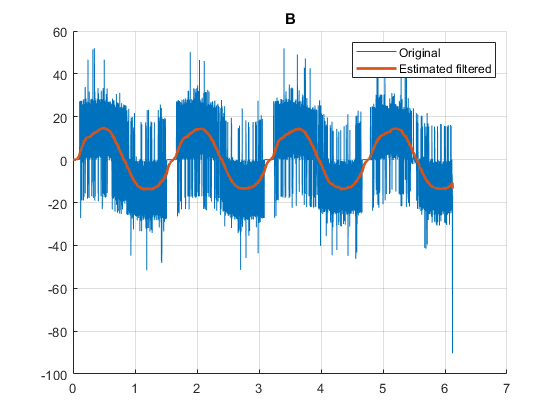


figure
hold on
% plot(time(start:finish), ddticks_orig(start:finish))
plot(time(start:finish), ddticks(start:finish))
plot(time(start:finish), x_arr(2, (start:finish)), "LineWidth", 2)
hold off
grid on
title("B")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

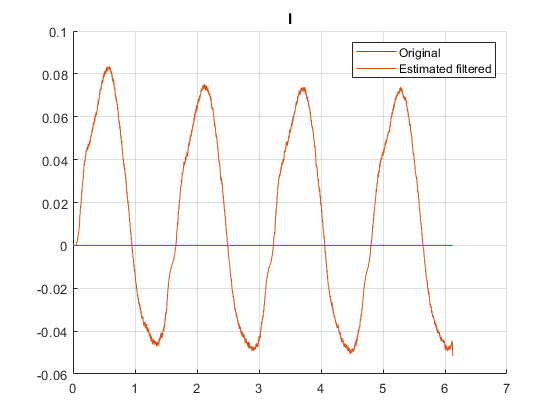


figure
hold on
plot(time(start:finish), current_orig(start:finish))
plot(time(start:finish), x_arr(3, (start:finish)))
hold off
grid on
title("I")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")